# BE Markov

## Triboulet Corentin

## Florian Beller

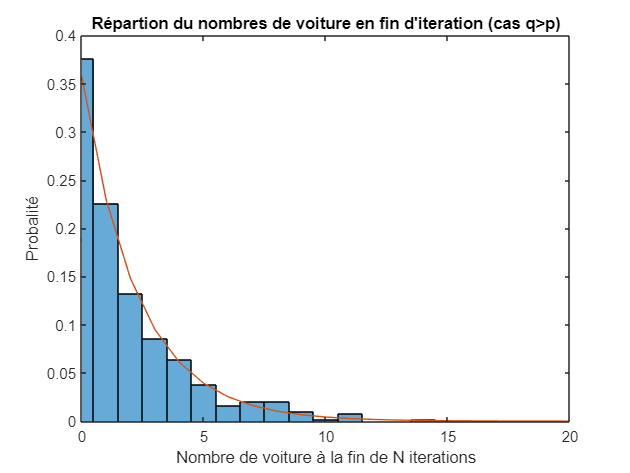


clear all;
close all;
p=0.6;
q=0.7;
N=500;
N_iter=500;
res=zeros(N,1);

for i=1:N
    Xn=floor(20*rand());
    for n=1:N_iter
        An=0;
        if rand()<p
            An=1;
        end
        Xn=Xn+An;
        if Xn>0 
            Dn=0;
            if rand()<q
                Dn=1;
            end
            Xn=Xn-Dn;
        end
    end
    res(i)=Xn;
end

pi=zeros(N_iter,1);
k=(1-q)*p/(1-p)/q;
pi(1)=1-k;
for i=2:N_iter;
    pi(i)=pi(i-1)*k;
end
histogram(res,Normalization='pdf')
title("Répartion du nombres de voiture en fin d'iteration (cas q>p)")
hold on
plot(0:N_iter-1,pi)
xlim([0 20])
xlabel("Nombre de voiture à la fin de N iterations")
ylabel("Probalité")

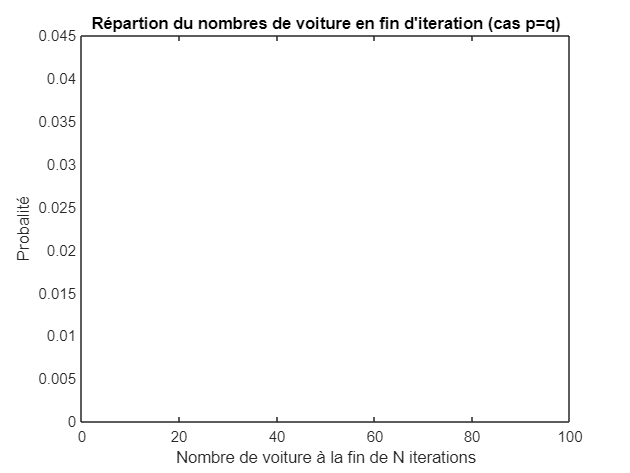

clear all;
close all;
p=0.6;
q=0.6;
N=10000;
N_iter=500;
res=zeros(N,1);
X0=25;
for i=1:N
    Xn=X0;
    for n=1:N_iter
        An=0;
        if rand()<p
            An=1;
        end
        Xn=Xn+An;
        if Xn>0 
            Dn=0;
            if rand()<q
                Dn=1;
            end
            Xn=Xn-Dn;
        end
    end
    res(i)=Xn;
end
r = chi2rnd(2,100,1);
[h,p_chi] = chi2gof(r,'cdf',@(res)chi2cdf(res,2),'nparams',1);

histogram(res,Normalization='pdf')
title("Répartion du nombres de voiture en fin d'iteration (cas p=q)")
xlabel("Nombre de voiture à la fin de N iterations")
ylabel("Probalité")
hold on
x = 0:1:N_iter;
y = gampdf(x,6,4);
xlim([0 100]);
plot(x,y)